%load data
%rna = readtable('mRna_sorted_out.csv','ReadRowNames',true);
%save('rna.mat', 'rna')

%mirna = readtable('mirna_sorted_out.csv','ReadRowNames',true);
%save('mirna.mat', 'mirna')

%cnv = readtable('CNV_sorted_out.csv','ReadRowNames',true);
%save('cnv.mat', 'cnv')

%mutation = readtable('mutation_sorted_out.csv','ReadRowNames',true);
%save('mutation.mat', 'mutation')

methylation = readtable('methylation_sorted_out.csv','ReadRowNames',true);

save('methylation.mat', 'methylation')

%protein = readtable('protein_sorted_out.csv','ReadRowNames',true);
%save('protein.mat', 'protein')

%clinical = readtable('clinical_sorted_out.csv','ReadRowNames',true);
%save('clinical.mat', 'clinical')

# **Lung Adenocarcinoma: Patient survival prediction.**

**A cancer patient data set containing 198 patient samples and approx 22k genes or features will be used to train a model to predict patient survival into three possible classes: alive, alive_relapse, relapse_dead.**

%load Data
%load('cnv.mat');
%load('mirna.mat');
%load('rna.mat');
%load('protein.mat');
load('methylation.mat');
%load('clinical.mat');
%load('response.mat', 'T');
%protein1=protein;
[d,t1] = xlsread('clinical_sorted_out.xlsx');
response = categorical(d(:,2));
methylation.class = response;
feature_table = methylation;

%Cnv = (table2array(feature_table))';
%rna = (table2array(rna))';
%mirna = (table2array(mirna))';
%protein = (table2array(protein))';
%mutation = (table2array(mutation))';
%clinical = (table2array(clinical))';
%response= (table2array(response))';
%x= {cnv; mirna; rna; protein; mutation};
%T=response;
%T=grp2idx(response);

% 
% % === train the network
% [net,tr] = train(net,P,T)

%x = P1;
%t = T;



rng(1)
% Use 70% of data for training and remaining for testing
split_training_testing = cvpartition(methylation.class, 'Holdout', 0.3);
% Dummyvar
methylation.class = dummyvar(methylation.class);
% Create a training set
training_set = feature_table(split_training_testing.training, :);

% Create a validation set
testing_set = feature_table(split_training_testing.test, :);

grpstats_training = grpstats(training_set, 'class', 'mean');
disp(grpstats_training(:,'GroupCount'))

         GroupCount
         __________

    0        88    
    1        51    




% Create a random sub sample (to speed up training) from the training set
subsample = [1:height(training_set)];

% Create a 5-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',5);

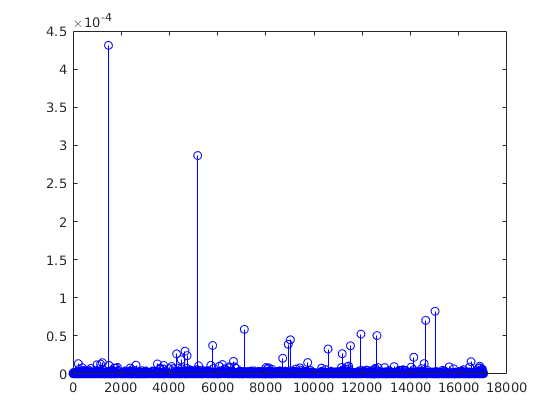

% Perform feature selection with neighborhood component feature selection
rng(1)
%test=training_set(:,477)
mdl = fscnca(table2array(training_set(:,1:(length(feature_table.Properties.VariableNames)-1))), ...
    table2array(training_set(:,length(feature_table.Properties.VariableNames))), 'Lambda', 0.005, 'Verbose', 0);

% Select features with weight above 1
selected_feature_indx = find(mdl.FeatureWeights > 0.1);


% Plot feature weights
stem(mdl.FeatureWeights,'bo');


% Load saved array of selected feature indexes to ensure reproducibility
%load('SelectedFeatures.mat')

% Display list of selected features
disp(feature_table.Properties.VariableNames(selected_feature_indx))
methylation_sel_features =feature_table.Properties.VariableNames(selected_feature_indx)


methylation_sel_features =

  1×0 empty cell array



%final_table = (table2array(feature_table(:,selected_feature_indx)))';
final_table = feature_table(:,selected_feature_indx);
writetable( final_table,'./NCA_outputs/methylation_sel_features_0genes.xlsx', 'WriteRowNames',true);

Error using writetable (line 142)
The data block starting at cell 'A1' exceeds the sheet boundaries by 0 row(s) and 0 column(s).

%csvwrite('./NCA_outputs/mutation_selected_features.csv', mutation_sel_features)

%Format output of clinical features for Neural network

d2 = d(:,[1,4:5])';
T = methylation.class;
resp_table= table(T);
writetable(resp_table, './NCA_outputs/response.xlsx');
gender = categorical(t1(2:end,10));
stage=categorical(t1(2:end,8));
tumor=categorical(t1(2:end,9));

t2=grp2idx(stage);
t3=grp2idx(tumor);
t4=grp2idx(gender);

final_clinical_table = table(d2',t2,t3,t4);
writetable(final_clinical_table, './NCA_outputs/Clin_feat_for_NN.xlsx','WriteRowNames',true);

rowNames = methylation.Properties.RowNames;
clin_feat ={'Age','pathology_N_stage','pathology_M_stage','pathology_stage','pathology_Tumor_stage','gender'};